# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 4-b. 샘플 데이터 시스템의 상태변수 모델**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2022b 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 샘플 데이터 시스템의 상태변수 모델

Topic 1에서는 4-a와 유사하게 연속 시간 시스템을 이산 시간 시스템으로 변환하는 `c2d` 함수를 이용하여 상태변수 모델을 이산화하도록 하겠습니다.

4-b는 4-a와 동일한 연속 시간 시스템을 고려합시다.


$$G_p(s)=\frac{1}{s+2}$$


num_Gp_tf = [1];
den_Gp_tf = [1 2];
Gp_tf_1 = tf(num_Gp_tf, den_Gp_tf);

수업시간의 내용을 통해 위의 전달함수를 아래와 같이 쉽게 상태변수 모델로 변환할 수 있습니다. 


$$\dot{x} = A_p x + B_p u = -2 x + 1u, \\
y=C_p x + D_p u = 1x + 0u$$


이제 ss 함수를 이용하여 ss 모델 객체로 정의되는 연속 시간 상태변수 모델을 아래와 같이 얻습니다. 

Ap = -2;
Bp = 1;
Cp = 1;
Dp = 0;
Gp_ss_1 = ss(Ap, Bp, Cp, Dp);

위의 연속 시간 시스템에 대한 샘플 데이터 시스템의 이산 시간 상태변수 모델은 다음과 같이 얻어집니다. 


$$x^d(k+1) = A^d x^d(k) + B^d u^d(k) = e^{A_p T} x^d(k) + \left(\int_0^T e^{A_p \tau}B d\tau\right) u^d(k)\\
y^d(k) = C^d x^d(k) + D^d u^d(k) = C x^d(k) + D u^d(k)$$


여기서 $A^d$와 $B^d$를 계산하는 것이 다소 까다로운데, 다행스럽게도 MATLAB에서는 연속 시간 모델에 c2d 함수를 적용하여 이 행렬들을 계산할 수 있습니다. 

T = 0.2;        % Sampling period;
Gd_ss_1 = c2d(Gp_ss_1, T, 'zoh');
Gd_ss_1

Gd_ss_1 =
 
  A = 
           x1
   x1  0.6703
 
  B = 
           u1
   x1  0.1648
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성


위에서 얻은 `Gd_ss_1`을 구성하는 $A^d$ 행렬은 다음과 같이 얻을 수 있습니다. (나머지 행렬들인 $B^d$, $C^d$, $D^d$들도 유사하게 얻을 수 있습니다.)

Gd_ss_1.A

ans = 0.6703

아래의 코드를 통해 위의 `Gd_ss_1.A`가 $e^{A_pT}$와 동일함을 쉽게 알 수 있습니다.

expm(Ap*T)

ans = 0.6703

### Topic 2 : 상태변수 모델과 전달함수 모델 간의 변환

`MATLAB`에서는 `ss` 모델 객체로 표현된 상태 변수 모델과 tf 모델 객체로 표현된 전달함수 모델 간의 변환을 쉽게 할 수 있습니다. 

예를 들어 `ss` 모델인 `Gd_ss_1`의 전달함수


$$C^d(zI-A^d)^{-1}B^d + D^d$$


는 다음과 같이 계산됩니다.

Gd_tf_1 = tf(Gd_ss_1)

Gd_tf_1 =
 
    0.1648
  ----------
  z - 0.6703
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


**이때 위의 **`tf`** 모델 **`Gd_tf_1`**는 4-a에서 계산한 펄스 전달함수 **$G^d(z) = \mathcal{Z} \left[G_p(s) \frac{1-e^{-Ts}}{s} \right]$**와 동일함에 주목합시다. **

c2d(Gp_tf_1,T,'zoh')

ans =
 
    0.1648
  ----------
  z - 0.6703
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


아래 코드를 통해 다시 `Gd_tf_1`을 상태변수 모델로 변환합시다.

ss(Gd_tf_1)

ans =
 
  A = 
           x1
   x1  0.6703
 
  B = 
        u1
   x1  0.5
 
  C = 
           x1
   y1  0.3297
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성


(상태변수 모델로부터 전달함수 모델로의 변환은 일반적으로 유일하지 않습니다. 따라서 2차 이상의 고차 시스템의 전달함수 모델을 상태변수 모델로 변환할 경우 기존의 상태변수 모델과 동일하지 않을 수 있습니다.)

### Topic 3 : Simulink 상에서 샘플 데이터 시스템 구현

지금부터는 `ss` 모델 객체로 표현된 샘플 데이터 시스템의 상태변수 모델을 `Simulink` 환경에서 구현해봅시다.

미리 작성된 `Simulink` 파일을 열어봅시다.

open('sim_topic3.slx');

Simulink 파일은 아래 그림과 같이 작성되어 있는데, 특히 상단부는 상태변수 모델 블록들을 이용하여 샘플 데이터 시스템과 등가적인 이산 시간 모델을 구현하였습니다. 

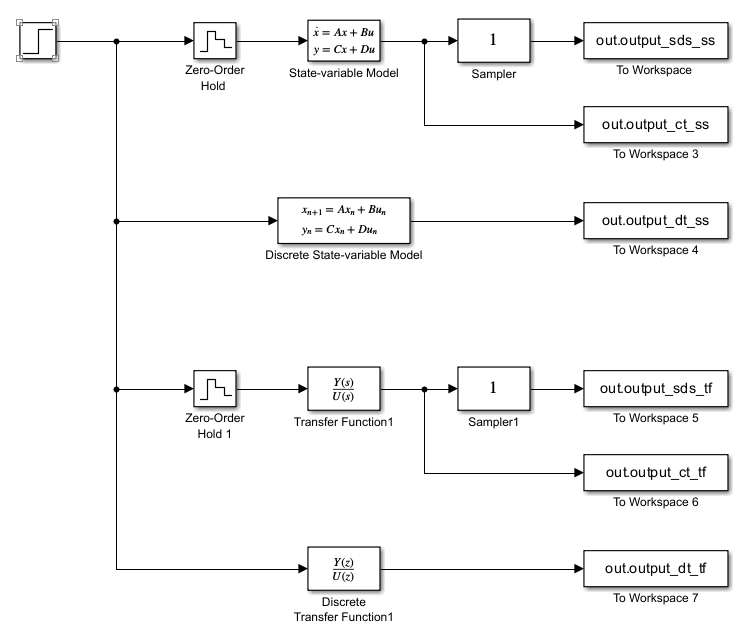

구현에 필요한 값들을 추가로 정의합니다. 

[num_Gd_tf_1, den_Gd_tf_1] = tfdata(Gd_tf_1);
num_Gd_tf_1 = num_Gd_tf_1{1};
den_Gd_tf_1 = den_Gd_tf_1{1};

이제 초기값 $x_0 = x(0) = x^d(0)$를 $1$로 선정하고 시뮬레이션해봅시다.

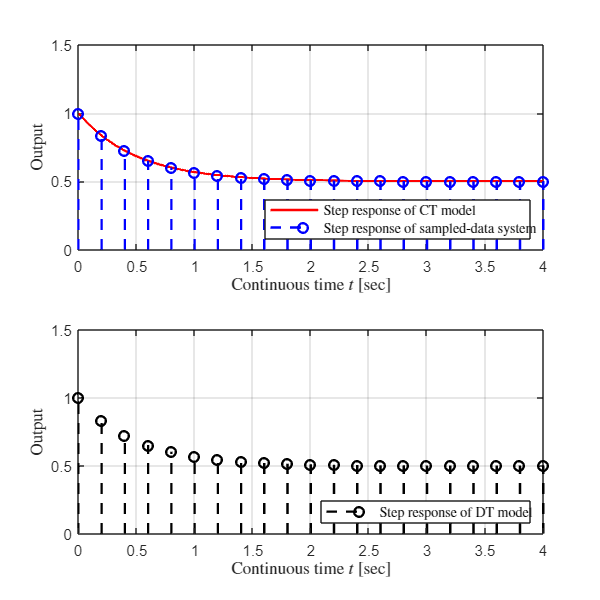

x0 = 1;
T_sim = 10;
dt_sim = 0.001;             % Simulation의 sampling period

sim('sim_topic3.slx');
simout = ans;

time_dt_sim3 = simout.time_dt;
time_ct_sim3 = simout.time_ct;
% State-variable models
output_dt_ss_sim3 = simout.output_dt_ss;
output_ct_ss_sim3 = simout.output_ct_ss;
output_sds_ss_sim3 = simout.output_sds_ss;
% Transfer function models
output_dt_tf_sim3 = simout.output_dt_tf;
output_ct_tf_sim3 = simout.output_ct_tf;
output_sds_tf_sim3 = simout.output_sds_tf;

f = figure();
f.Position = [100 100 500 500];
subplot(2,1,1)
    plot(time_ct_sim3,output_ct_ss_sim3,'r','LineWidth',1.5);
    hold on;
    stem(time_dt_sim3,output_sds_ss_sim3,'--b','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output','Interpreter','latex');
    xlim([0 4]); 
    ylim([0 1.5]);
    legend('Step response of CT model','Step response of sampled-data system','Interpreter','latex','Location','southeast'); 
subplot(2,1,2)
    stem(time_dt_sim3,output_dt_ss_sim3,'--k','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output','Interpreter','latex');
    xlim([0 4]); 
    ylim([0 1.5]);
    legend('Step response of DT model','Interpreter','latex','Location','southeast'); 

위와 같이 샘플 데이터 시스템 모델과 등가적인 이산 시간 모델 모두 동일한 입출력 관계를 보여줌을 확인할 수 있습니다.

그런데 한 가지 유의할 점은, 정작 상태변수 모델과 전달함수 모델의 입출력 관계는 달라보인다는 점입니다.

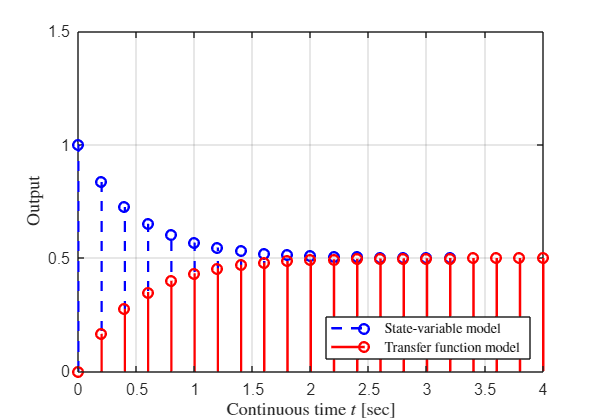

f = figure();
f.Position = [100 100 500 350];
stem(time_dt_sim3,output_sds_ss_sim3,'--b','LineWidth',1.5);
hold on;
stem(time_dt_sim3,output_sds_tf_sim3,'r','LineWidth',1.5);
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Output','Interpreter','latex');
xlim([0 4]); 
ylim([0 1.5]);
legend('State-variable model','Transfer function model','Interpreter','latex','Location','southeast'); 

이는 사실 초기값 설정과 관련되어 있습니다. 상태변수 모델은 아래 그림처럼 초기 조건을 0이 아닌 값으로 설정해주었습니다.

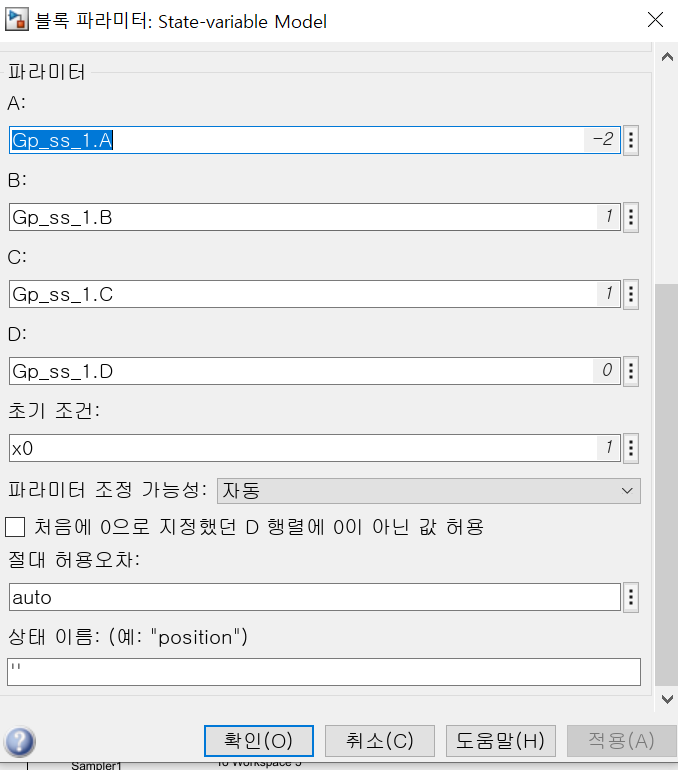

반면 전달함수 모델은 아래 그림과 같이 초기 상태를 0으로 설정하였기 때문에, 과도 상태에서의 응답이 달라지게 되었습니다.